**Turbulence Part**

clear 
clc

n =3500;

Ts= 1;

muw = 10;

ti = 0.2; %turbulence itencity

CV = ti*muw;

 

Wt= zeros(1,n);

wp = (muw*pi)/(2*340.2);

at = exp(-wp*Ts)

at = 0.9549



stdt= (ti *muw*sqrt(1-at^2));

for i=2 :n
    et = normrnd(0,stdt^2);
    Wt(i) = at * Wt(i-1)+ et;  
end


**Slow Part**




q = 2^2/600 ; %slow part changinf by 2m/s over 10 min.

stdw = sqrt(Ts*q);
Ws(1) = 10;
for i=2 :n
    es = normrnd(0,stdw);
    Ws(i) = Ws(i-1)+ es;  
end


for i=1 :n
    W(i)  = Ws(i) + Wt(i);  
end


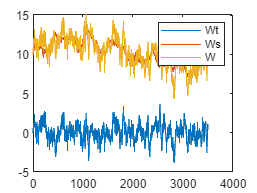





figure(1)
plot(Wt)
hold on
plot(Ws)
plot(W)
hold off
legend("Wt","Ws","W")


exportgraphics(gcf,'WindSim.pdf','ContentType','vector')